# Escape Detect

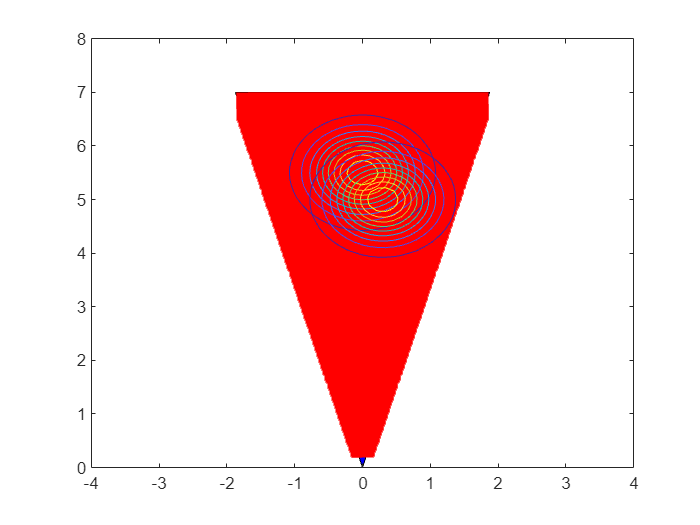

clear;clc;close;

% Parameter
range = 5; lambda = 2; AOV = pi/6; alpha = AOV*0.5;
pos = [0;0]; perspective = [0;1]; perspective = perspective/norm(perspective);

range_max = ( (lambda+1)/lambda )*range*cos(alpha);
R = [cos(alpha) -sin(alpha);sin(alpha) cos(alpha)];

top = pos + range_max*perspective;
ltop = pos + range_max*( R*perspective );
rtop = pos + range_max*( (R')*perspective);

% Event & Joint Probability
p0 = 0.2;
p = @(d, a) ( ((d-range_max).^2).*((a-alpha).^2) )./( (range_max.^2).*(alpha.^2) );
T = @(d, a) p0.*exp( -((d-range_max).^2 )./(2*0.5^2) ).*exp( -((a-alpha).^2 )./(2*0.5^2) );

p_ = @(d, a) ( ((d).^2).*((a).^2) )./( (range_max.^2).*(alpha.^2) );
% p_ = @(d, a) exp( -((d-range_max).^2 + (a-alpha).^2)./(2*0.36^2) );

f1 = @(x) exp( -(vecnorm(x-[0;5.5])).^2./(2*0.5^2) );
f1_ = @(x, y) exp( -( (x-0).^2 + (y-5.5).^2 )./(2*0.5^2) );
f2 = @(x) exp( -(vecnorm(x-[0.3;5])).^2./(2*0.5^2) );
f2_ = @(x, y) exp( -( (x-0.3).^2 + (y-5).^2 )./(2*0.5^2) );
f3 = @(x) exp( -(vecnorm(x-[-0.3;5])).^2./(2*0.5^2) );
f3_ = @(x, y) exp( -( (x+0.3).^2 + (y-5).^2 )./(2*0.5^2) );

% Plot
% Define the vertices of the triangle
A = [pos(1) pos(2)];
B = [ltop(1) ltop(2)];
C = [rtop(1) rtop(2)];

% Define the x and y ranges with a spacing of 0.1
x_range = ltop(1)+0.1:0.01:rtop(1)-0.1;
y_range = 0.3:0.01:rtop(2)-0.1;

% Generate a grid of points within the x and y ranges
[X, Y] = meshgrid(x_range, y_range);

% Reshape the grid into a list of points
points = [X(:) Y(:)];

% Select only the points within the triangle
in_triangle = inpolygon(points(:,1), points(:,2), [A(1) B(1) C(1)], [A(2) B(2) C(2)]);
points = points(in_triangle, :);

% Plot the triangle and the generated points
figure;
fill([A(1) B(1) C(1)], [A(2) B(2) C(2)], 'blue');
hold on;
plot(points(:,1), points(:,2), 'rx', 'MarkerSize', 10);
fcontour(f1_);
fcontour(f2_);
% fcontour(f3_);
hold off
xlim([-4 4]); ylim([0 8]);

% Environment
% x = 0:0.1:1; y = 0:0.1:7;
% W = zeros(2,length(x)*length(y));
% 
% for i = 1:length(x)
%     for j = 1:length(y)
% 
%         W(:,j+length(y)*(i-1)) = [x(i);y(j)];
%     end
% end
% 
% W = W(:,2:end);
W = points';
d_W = vecnorm(W-pos);
a_W = acos( ((W-pos)./d_W)'*perspective );

JP_W = p(d_W, a_W');
% JP_W = T(d_W, a_W');
F1_W = f1(W);
F2_W = f2(W);
F3_W = f3(W);
H_W = sum(F1_W.*JP_W)+sum(F2_W.*JP_W)+sum(F3_W.*JP_W);

JP_W_I = p_(d_W, a_W');
H_W_I = sum(F1_W.*JP_W_I)+sum(F2_W.*JP_W_I)+sum(F3_W.*JP_W_I);

% Boundary
% l_side_x = linspace(pos(1)+0.0, ltop(1)+0.1, norm(pos-ltop)/0.1);
% l_side_y = linspace(pos(2)+0.1, ltop(2)-0.1, norm(pos-ltop)/0.1);
% l_side = [l_side_x;l_side_y];
% 
% lt_side_x = linspace(ltop(1)-0.1, top(1)-0.0, norm(ltop-top)/0.1);
% lt_side_y = linspace(ltop(2)-0.1, top(2)-0.1, norm(ltop-top)/0.1);
% lt_side = [lt_side_x;lt_side_y];
% 
% tr_side_x = linspace(top(1)-0.0, rtop(1)-0.1, norm(top-rtop)/0.1);
% tr_side_y = linspace(top(2)-0.1, rtop(2)-0.1, norm(top-rtop)/0.1);
% tr_side = [tr_side_x;tr_side_y];
% 
% r_side_x = linspace(rtop(1)-0.1, pos(1)+0.0, norm(rtop-pos)/0.1);
% r_side_y = linspace(rtop(2)-0.1, pos(2)+0.1, norm(rtop-pos)/0.1);
% r_side = [r_side_x;r_side_y];
% 
% side = [l_side, lt_side, tr_side, r_side];
% d_side = vecnorm(side-pos);
% a_side = acos( ((side-pos)./d_side)'*perspective );
% 
% JP_side = p_(d_side, a_side');
% F_side = f(side);
% H_side = sum(F_side.*JP_side);